Rozwinięcie funkcji $f\left(x\right)$ w szereg Taylora wokół punktu $x_0$ pozwala obliczyć wartości $f\left(x\right)$na podstawie znajomości $f\left(x_0 \right)$ oraz jej pochodnych: $f^{\left(1\right)} \left(x_0 \right)$, $f^{\left(2\right)} \left(x_0 \right)$, ..., $f^{\left(\infty \right)} \left(x_0 \right)$.


$$f\left(x_0 -x\right)\cong \sum_{k=1}^n f^{\left(k\right)} \left(x_0 \right)\frac{{\left(x-x_0 \right)}^k }{k!}$$


clear all;
close all;
%zwybór funkcji, która zostanie rozwinięta w szereg Taylora
syms f(x)
f(x)=sin(x)

$$f(x) = \sin\left(x\right)$$


%wybór liczby czynników rozwinięcia
n=4

n = 4


%Uruchom z wartościami domyślnymi
deafVal=true

deafVal = logical
   1


 

if deafVal==true
    x0=4
    a=-10
    b=10
else
    x0=input("Podaj punkt, wokół którego zostanie rozwinięta funkcja:")
    a=input("Podaj lewy kraniec wykresu:")
    if a>=x0
        display('Uwaga, miejsce rozwiniecia w szereg bedzie poza wykresem!')
    end
    b=input("Podaj prawy kraniec wykresu:")
    if b<=x0
        display('Uwaga, miejsce rozwiniecia w szereg bedzie poza wykresem!')
    end
    if a>=b
        display("Prawy kraniec przedziału musi być liczbą większą od lewego krańca.")
        return
    end
end

x0 = 4

a = -10

b = 10

%x0=0;
%a=-pi;
%b=pi;


f0=double(f(x0));
display("Wartość funkcji w punkcie x0: " + f0 + ".")

    "Wartość funkcji w punkcie x0: -0.7568."




fprimsym=[];
for i=1:n-1
    fprimsym=[fprimsym; diff(f,i)];
    fprim=double(fprimsym(x0));
    display("Wartość "+i+" pochodnej funkcji w punkcie x0: "+fprim(i)+".")
    %disp()
end

    "Wartość 1 pochodnej funkcji w punkcie x0: -0.65364."

    "Wartość 2 pochodnej funkcji w punkcie x0: 0.7568."

    "Wartość 3 pochodnej funkcji w punkcie x0: 0.65364."



display("Pierwsze "+i+" pochodnych funkcji f(x): ")

    "Pierwsze 3 pochodnych funkcji f(x): "



fprimsym

$$fprimsym(x) = \left(\begin{array}{c} \cos\left(x\right)\\ -\sin\left(x\right)\\ -\cos\left(x\right) \end{array}\right)$$

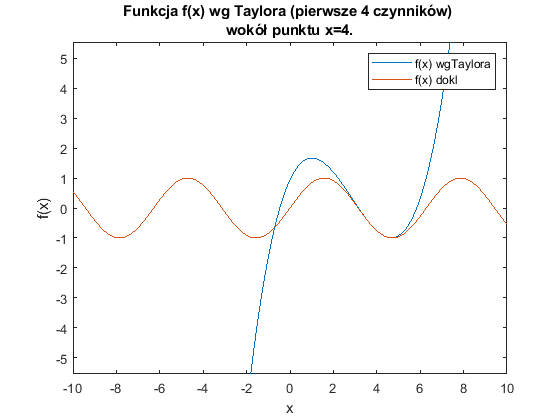


tfprim=transpose(fprim);
X=linspace(a,b,10000);
fun_dokl=double(f(X));
fun_T=f0*X.^0;
for i=1:n-1
    fun_T= fun_T+tfprim(i)*(X-x0).^(i)/factorial(i);
end
figure()
plot(X,fun_T,X,fun_dokl)
title("Funkcja f(x) wg Taylora (pierwsze "+n+" czynników) " + sprintf('\n') + "wokół punktu x=" + x0 + ".")
xlabel('x')
ylabel('f(x)')
legend('f(x) wgTaylora','f(x) dokl')
ylim([min(double(f(a)),double(f(b)))-5, max(double(f(a)),double(f(b)))+5])
xlim([a b])

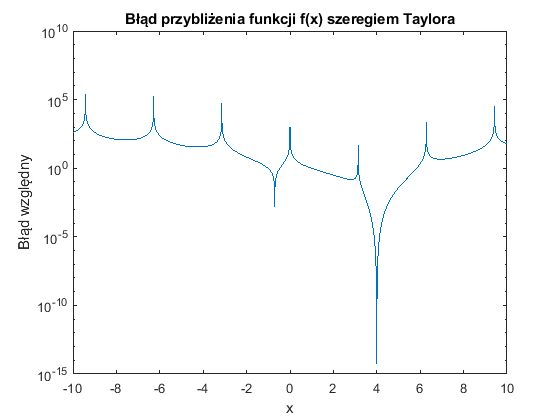


figure()
semilogy(X,abs((fun_T-fun_dokl)./fun_dokl))
title("Błąd przybliżenia funkcji f(x) szeregiem Taylora")
xlabel('x')
ylabel('Błąd względny')
xlim([a b])

Zwróć uwagę, że:

- Rysunki można powiększać, resetować powiększenie, przesuwać, otworzyć w odzdzielnym oknie, wyeksportować itp. - za pomocą ikonek, które pojawiają się po najechaniu kursorem w prawy górny obszar figury.

- Czynnik pierwszy rozwinięcia w szereg Taylora jest składową stałą, czynnik drugi jest funkcją liniową, czynnik trzeci jest wielomianem drugiego stopnia itd. - inaczej mówiąc szereg Taylora, to suma wielomianów.

- Po uwzględnieniu wystarczającej liczby (skończonej) czynników każdy wielomian zostanie odtworzony w sposób dokładny.

- Błędy wyświetlane przez maszynę w takim przypadku są efektem zjawisk numerycznych (np. transmisji błędów reprezentacji itp), o których będziemy mówić w trakcie WNUM.

- Funkcje niewielomianowe nie dają się odtworzyć dokładnie za pomocą skończonej liczby czynników szeregu Taylora.

- Przybliżenie funkcji jest zawsze bardzo dobre w bezpośredniej bliskości punktu rozwinięcia.

- Generalnie rysują się różne piękne kształty!

Uruchom skrypt ZW_9_Quiz.p.

Jeżeli masz wątpliwość jaka powinna być poprawna odpowiedź wróć tutaj - pytania są tak skonstruowane, żeby odpowiedź na nie można było sprawdzić za pomocą powyższego programu!